# Using Mathematics to Make and Stream Music

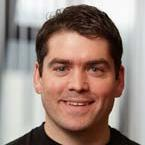

**Dr Jon Shiach**

**Department of Computing and Mathematics**

**Email:** j.shiach@mmu.ac.uk 

## Introduction

This MATLAB live script is designed to accompany a session which introduces you to the mathematics used in the creating of digital music and also the streaming of music which is used by applications such as Spotify, YouTube and TikTok. Whilst some of the mathematics required is ordinarily taught at degree level, to follow the content of this notebook you just need an understanding of **radians**, the **sine** and **cosine** functions (which are covered in the preliminaries section below) and a little curiosity. This notebook contains some MATLAB code to perform calculations, produce plots and play audio signals. No programming experience is necessary to follow the examples, however, readers can make changes to the code and execute to see what affects any changes has on the output.

## Preliminaries

Here I will introduce you to the mathematical and Python concepts that you need to understand the content of this live script. 

### Radians

A radian is simply a measure of the size of an angle. You may be familiar with measuring angles with degrees where there are $360^\circ$ in a circle and a right-angle is $90^\circ$ and so on. In mathematics we prefer to measure angles in radians because it is more convenient for some applications and makes our formulas more elegant. 

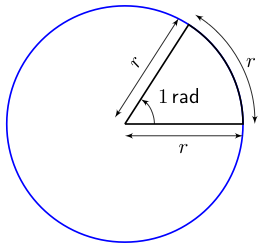

Consider the diagram of the circle. To define a radian we do the following

- Draw a circle.

- Draw a line from the centre to the edge of the circle.

- Where your line meets the edge of the circle, draw an arc around the circle which has the same length as the radius of your circle.

- Where your arc ends, draw a line to the centre of the circle

The angle between the two lines that meet at the centre is 1 radian. Since the circumference of the circle can be calculated using $2\pi r$ then length of our arc is 


$$r = 2 \pi r \left( \frac{1 \text{ rad}}{360^\circ} \right).$$


Rearranging this gives the conversion between degrees and radians of $360^\circ = 2\pi \text{ rad}$ (the unit $\text{rad}$ is usually omitted).

### The sine and cosine functions

The sine and cosine functions are used in trigonometry to calculate the length of the sides of a right-angled triangle. Consider the triangle $ABC$ where the angle at point $B$ is a right-angle. The longest side of the triangle is labelled the **hypotenuse** and the two shorter sides are labelled **adjacent** and **opposite** depending on their position relative to the angle $\theta$ (the character $\theta$ is the Greek letter *theta* and is commonly used to represent angles in mathematics) which in this is at the point $A$. 

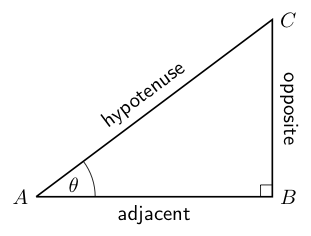

The definition of the sine and cosine functions are related to the lengths of the sides of a right-angled triangle as follows


$$\sin(\theta) = \frac{\text{opposite}}{\text{hypotenuse}}, \\
\cos(\theta) = \frac{\text{adjacent}}{\text{hypotenuse}}.$$


So if $\theta = 0.6435$ and the length of the hypotenuse is $5$ then we can calculate the length of the opposite and adjacent sides using


$$\text{opposite} = \text{hypotenuse} \times \sin(\theta) = 5\sin(0.6435) \approx 3, \\
\text{adjacent} = \text{hypotenuse} \times \cos(\theta) = 5\cos(0.6435) \approx 4.$$


We can check whether these are correct using the [Pythagorean theorem](https://en.wikipedia.org/wiki/Pythagorean_theorem), i.e., $5 ^ 2 = 3 ^ 2 + 4 ^ 2 = 9 + 16 = 25$.

- ***NOTE:***  When using radians to measure the size of an angle your need to make sure your calculator is in radians mode as opposed to degrees mode else you answers will be wrong! How you switch modes will depend on your calculator but usually there is a small 'R' or 'D' on the display to indicate with mode you are in. Programming languages such as Python use radians by default.

## Co-ordinates of points on a circle

We can use sine and cosine functions to calculate the co-ordinates of points on a circle. Consider the diagram on the right which shows the upper right-hand quadrant of a circle which is centred at the origin and has a radius of $r$. 

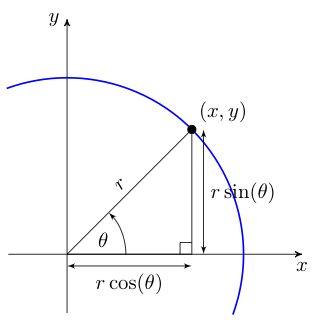

For every point in this quadrant of the circle we can form a right angled triangle where the length of the hypotenuse is $r$. If the angle $\theta$ is the angle between the $x$ axes and the hypotenuse then $x$ co-ordinate of the point on the circle is equal to the length of the adjacent side of the triangle and the $y$ co-ordinate is equal to the length of the opposite side, therefore


$$(x, y) = (r \cos(\theta), r \sin(\theta)).$$


We can continue this for the other quadrants in the circle, i.e., for angles $\theta > \frac{\pi}{2}$.

The table below shows the co-ordinates of points on a circle with radius $r=3$ using angles $\theta = 0, \frac{\pi}{4}, \frac{2\pi}{4}, \frac{3\pi}{4} \ldots , 2\pi$ which are plotting below. Try changing the value of the radius to see what changes this has to the co-ordinates.

% Calculate (x, y) co-ordinates for points on a circle
r = 3;               % radius of the circle
thetavals = (0 : 8) * pi / 4;         % calculate θ values
xcoord = r * cos(thetavals);          % calculate x = r cos(θ)
ycoord = r * sin(thetavals);          % calculate y = r sin(θ)

% Print a table of θ and the x and y co-ordinates
T = table(thetavals', xcoord', ycoord', 'VariableNames',{'θ', 'x', 'y'})

T = 9×3 table
      θ            x              y     
    ______    ___________    ___________

         0              3              0
    0.7854         2.1213         2.1213
    1.5708      1.837e-16              3
    2.3562        -2.1213         2.1213
    3.1416             -3     3.6739e-16
     3.927        -2.1213        -2.1213
    4.7124    -5.5109e-16             -3
    5.4978         2.1213        -2.1213
    6.2832              3    -7.3479e-16


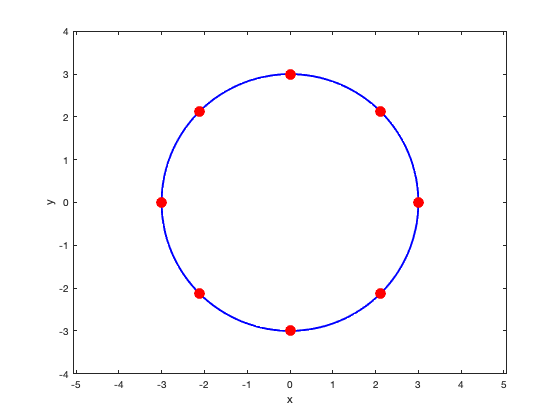

% Plot circle
clf
theta = linspace(0, 2 * pi, 200);
plot(r * cos(theta), r * sin(theta), 'b', 'linewidth', 2)
hold on
plot(xcoord, ycoord, 'ro', 'markerfacecolor', 'r', 'markersize', 10)
hold off
axis([-1 - r, 1 + r, -1 - r, 1 + r])
axis equal
xlabel('x')
ylabel('y')

## Sine waves

We can plot the $y$ co-ordinate of the points on the circle against the values of $\theta$ by plotting the point with co-ordinates $(\theta, \sin(\theta))$ on an axes and drawing a smooth line connecting the points. This will produce a plot of the sine wave shown below.

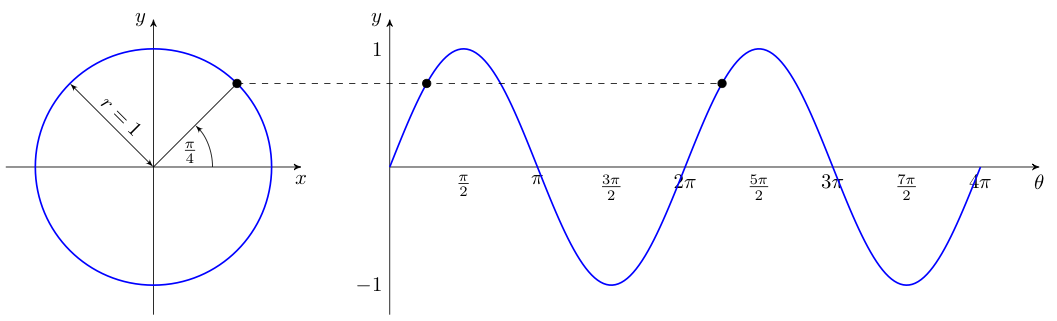

Note how the curve repeats itself after $\theta = 2\pi$ and it will continue to do so as $\theta$ increases to $\infty$ and also as $\theta$ decreases to $-\infty$. In the plot above we see that $\sin\left(\frac{\pi}{4}\right) = \sin\left(\frac{\pi}{4} + 2\pi\right)$ and we can extend this to all angles where $\sin(\theta) = \sin(\theta + 2 \pi) = \sin(\theta + 4 \pi) = \ldots = \sin(\theta + n2\pi)$ where $n$ is any whole number. This is because on the $xy$-axes on the left when $\theta=2\pi$ we have completed one complete rotation around the circle and have returned to the 3 o'clock position at $(r, 0)$. The $x$ and $y$ co-ordinates will start to repeat themselves so on the $\theta y$-axes on the right we see the repeating wave pattern. We say that the sine function is a **periodic function** with a period of $2\pi$ (which is also the case for the cosine function) .

The MATLAB code below calculates the function $y = \sin(\theta)$ for $\theta$ values in the range $0 \leq \theta \leq 4\pi$ and plots the sine wave.

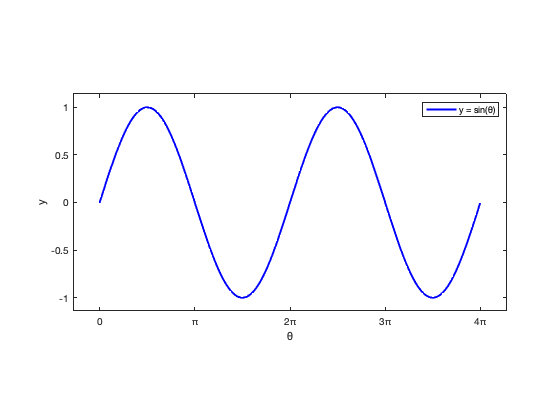

% Calculate y = sin(θ) for the range 0 <= θ <= 4π
theta = linspace(0, 4 * pi, 200);
y = sin(theta);

% Plot sine curve
plot(theta, y, 'b', 'linewidth', 2)
legend('y = sin(θ)')
pbaspect([2, 1, 1])
axis padded
xlabel('θ')
ylabel('y')
xticks((0:4) * pi)
xticklabels({'0', 'π', '2π', '3π', '4π'})

### Amplitude

The **amplitude** of a wave is the largest difference between the wave and zero. Since our sine curve is related to the $y$ co-ordinates of points on a circle which are at their largest when $\theta = \frac{\pi}{2}$ and $\theta = \frac{3\pi}{2}$ (here we are ignoring the sign of $y$) where $\sin(\theta) = 1$ is equal to the radius of the circle. Therefore we can increase or decrease the amplitude of a sine wave by changing the radius of the circle. So if we say that $A$ is the amplitude then $r=A$ and the sine curve is 


$$y = A \sin(\theta).$$


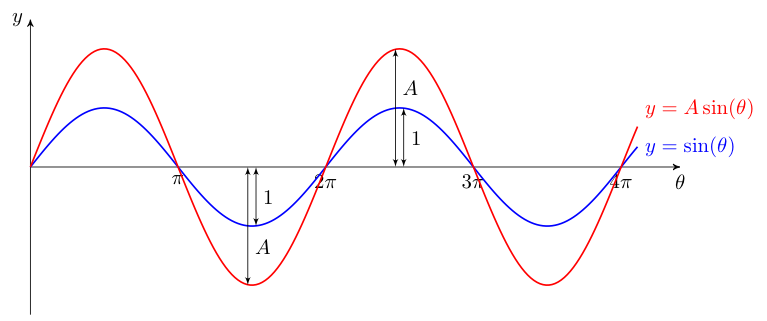

In audio signals, we can think of the amplitude as being the volume of the sound.

Below is a plot of the curve of $y = A\sin(\theta)$ for $\theta$ values in the range $0 \leq \theta \leq 4\pi$. Try experimenting with changing the value of `A` and see what affects this has on the shape of the curve.

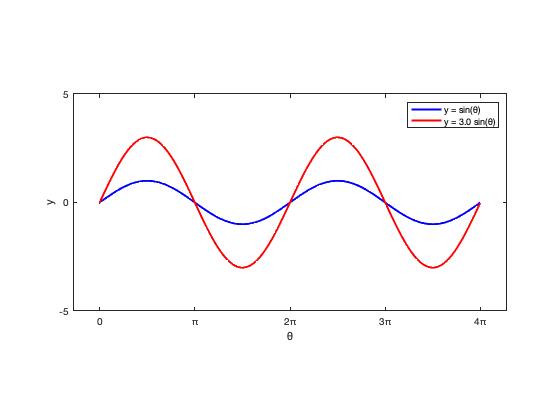

% Calculate y = A sin(θ) for the range 0 <= θ <= 4π
A = 3;
y1 = A * sin(theta);

% Plot the sine curves
clf
plot(theta, y, 'b', 'linewidth', 2)
hold on
plot(theta, y1', 'r', 'linewidth', 2)
hold off
legend('y = sin(θ)', sprintf('y = %1.1f sin(θ)',A))
pbaspect([2, 1, 1])
axis padded
ylim([-5, 5])
xlabel('θ')
ylabel('y')
xticks((0:4) * pi)
xticklabels({'0', 'π', '2π', '3π', '4π'})

### Frequency

The **frequency** of a wave is the number of times the wave repeats over an interval of $0 \leq \theta \leq 2\pi$ radians. If we consider the [points on a circle from before](#Sine-waves), if we multiply the angle $\theta$ by 2 before calculating the $(x, y)$ co-ordinates of the points on the circle then the points will do 2 revolutions of the circle over the interval $0 \leq \theta \leq 2\pi$. The curve of $y = \sin(2\theta)$ will look like the diagram below

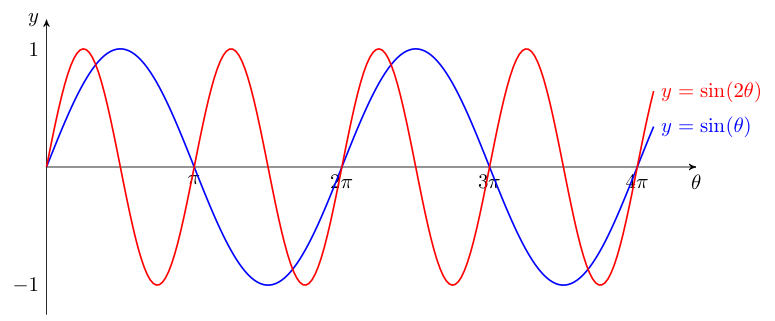

The frequency of a sine wave is represented using $f$ so our sine function becomes


$$y = \sin(f\, \theta).$$


By increasing the value of $f$ we increase the number of times we do a revolution of the circle which has the affect of reducing the spacing between the peaks and troughs of the sine wave. In audio signals we think of the frequency as the pitch of the sound. Waves with higher frequencies have a higher pitched sound and waves with lower frequencies have a lower pitched sound. 

The code below plots the curve of $y = \sin(2 \theta)$ for $\theta$ values in the range $0 \leq \theta \leq 4\pi$. Try experimenting with changing the value of the frequency `f` and see what affects this has on the shape of the wave.

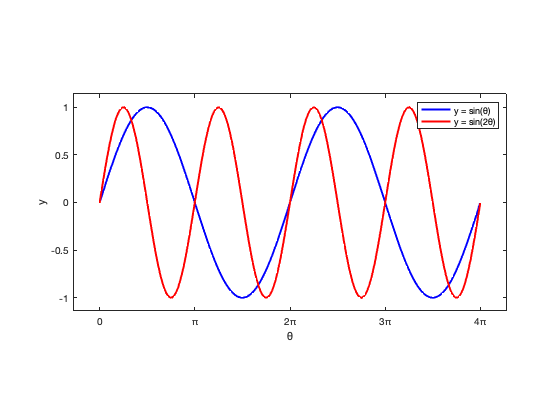

% Calculate y = sin(fθ) for the range 0 <= θ <= 4π
f = 2;
y1 = sin(f * theta);

% Plot the sine curves
clf
plot(theta, y, 'b', 'linewidth', 2)
hold on
plot(theta, y1', 'r', 'linewidth', 2)
hold off
legend('y = sin(θ)', sprintf('y = sin(%1iθ)', f))
pbaspect([2, 1, 1])
axis padded
xlabel('θ')
ylabel('y')
xticks((0:4) * pi)
xticklabels({'0', 'π', '2π', '3π', '4π'})

### Phase angle

The **phase angle** of a sine wave is an angle $\phi$ ($\phi$ is the Greek character *phi*) that is added to the angle $\theta$ within the sine function, i.e.,


$$y = \sin(\theta + \phi).$$


If we think about the [points on a circle from before](#Sine-waves), adding a positive phase angle $\phi$ to $\theta$ before calculating the $(x, y)$ co-ordinate of a point on a circle then this has the affect of moving the point further around the circle in the anti-clockwise direction. The affect this has on the sine wave is to shift it to the left along the $\theta$ axis by the distance $\phi$ as shown in the diagram below. Adding a negative $\phi$ value will shift the wave to the right.

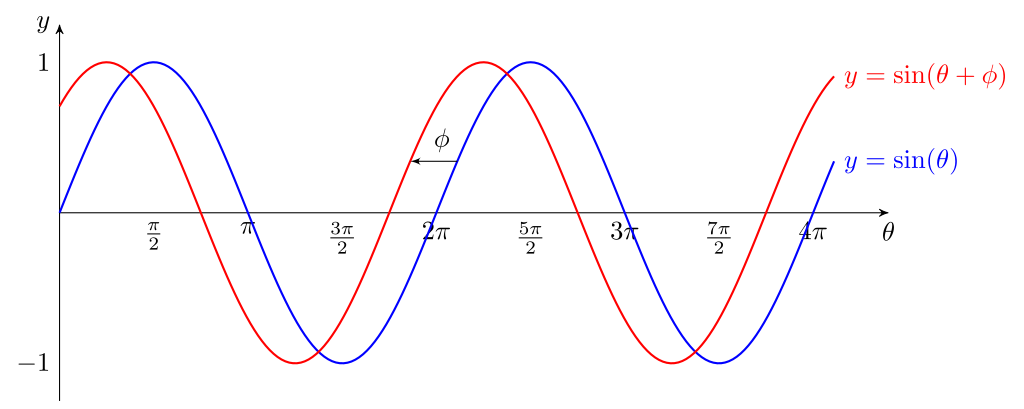

In music we can think of the phase angle as introducing a delay in the sound.

Below is a plot of the curve of $y = \sin(\theta + \phi)$ for $\theta$ values in the range $0 \leq \theta \leq 4\pi$. Try experimenting with changing the value of the phase angle `phi` and see what affects this has on the sine curve.

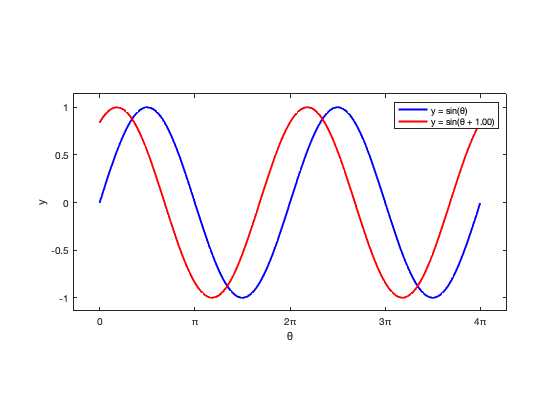

% Calculate y = sin(θ + ϕ) for the range 0 <= θ <= 4π
phi = 1;
y1 = sin(theta + phi);

% Plot the sine curves
clf
plot(theta, y, 'b', 'linewidth', 2)
hold on
plot(theta, y1', 'r', 'linewidth', 2)
hold off
legend('y = sin(θ)', sprintf('y = sin(θ + %1.2f)', phi))
pbaspect([2, 1, 1])
axis padded
xlabel('θ')
ylabel('y')
xticks((0:4) * pi)
xticklabels({'0', 'π', '2π', '3π', '4π'})

### Adding sine waves together

So we have seen that we can control the shape of a sine wave by changing the amplitude ($A$) frequency ($f$) and phase angle ($\phi$). Combining these we have the following function that describes a sine wave


$$y = A \sin(f\theta + \phi).$$


We can also add sine waves together which will form other waves. For example the diagram below shows the sum of the three sine waves with amplitudes $A = 2, \frac{2}{3}, \frac{2}{5}$ and frequencies $f = 1, 3, 5$ so the wave is now described by


$$y = 2 \sin(\theta) + \frac{2}{3}\sin(3\theta) + \frac{2}{5}\sin(5\theta).$$


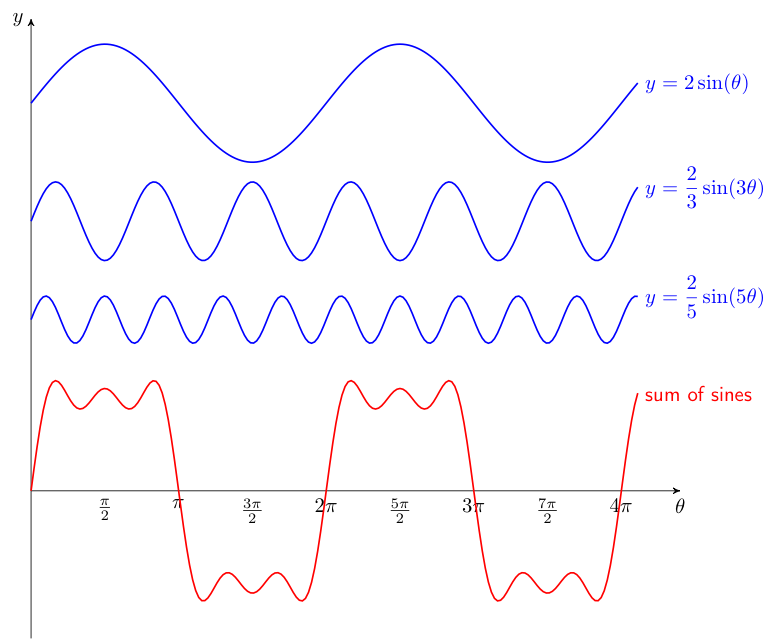

The plots below show 3 sine waves with different values of $A$, $f$ and $\phi$. Note how by adding these sine functions together we have a curve that resembles a music signal. This means that we can represent a music signal as the sum of multiple sine waves! Try experimenting with creating different waves by changing the values of the amplitudes, frequencies and phase angles.

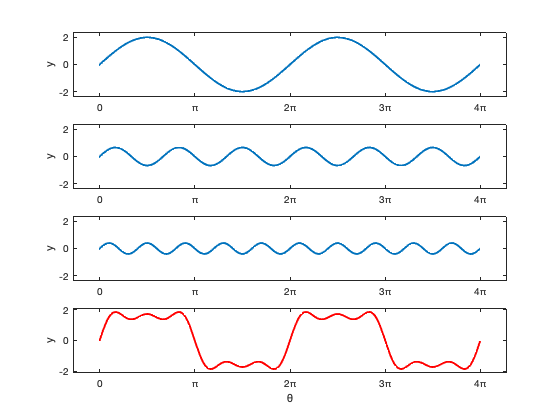

% Define the amplitudes, frequencies and phase angles
A = [2, 2/3, 2/5];
f = [1, 3, 5];
phi = [0, 0, 0];
A(1) = 2; f(1) = 1; phi(1) = 0;
A(2) = 2/3; f(2) = 3; phi(2) = 0;
A(3) = 2/5; f(3) = 5; phi(3) = 0;

% Calculate the sine waves
ysum = zeros(size(theta));
for i = 1 : length(A)
    ysum = ysum + A(i) * sin(f(i) * theta + phi(i));
end

% Plot sine functions
clf
for i = 1 : length(A)
    subplot(length(A) + 1, 1, i)
    plot(theta, A(i) * sin(f(i) * theta + phi(i)), 'linewidth', 2)
    axis padded
    ylim([-1.2 * max(A), 1.2 * max(A)])
    ylabel('y')
    xticks((0:4) * pi)
    xticklabels({'0', 'π', '2π', '3π', '4π'})
end

subplot(length(A) + 1, 1, i + 1)
plot(theta, ysum, 'r', 'linewidth', 2)
axis padded
xlabel('θ')
ylabel('y')
xticks((0:4) * pi)
xticklabels({'0', 'π', '2π', '3π', '4π'})

## Using sine waves to make music

Now that we know how to work with sine waves we are now look at how they can be used to make audio signals of musical notes and chords. The mathematics shown here is used in electronic instruments such as keyboards to produce sounds.

Here we will try to recreate piano notes using sine waves. There are 88 keys on a standard modern piano, 52 white keys and 36 black keys. When a key is pressed it causes a hammer to strike a string and the vibration of the string disturbs the air to produce the sound we hear. In a real acoustic instrument the sound of the note decreases over time. The keys to the left of the piano produce notes with a lower pitch and the keys to the right produces notes is a higher pitch.

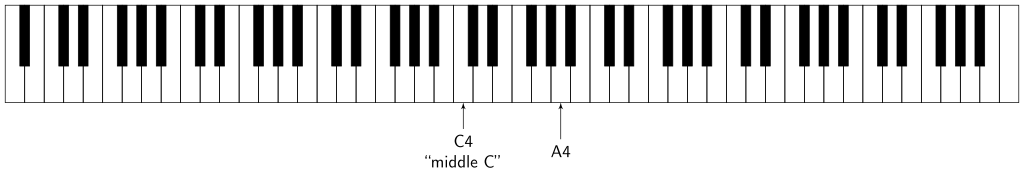

So if we want to recreate piano notes we need to be able to produce audio signals that have the same pitch as a piano note and we need the volume to decrease over time.

### Generating a musical note

An audio signal is represented over time so we need a way to convert between the angle $\theta$ in the sine function and time $t$ in seconds. The unit of measure for frequency is **Hertz** abbreviated to Hz (named after German physicist Heinrich Rudolf Hertz, 1857 - 1894), which is defined as the number of cycles per second. So if we have a signal with a frequency of 1 Hz the one cycle of a circle is equivalent to 1 second in time. Since there are $2\pi$ radians in a circle then $\theta = 2\pi f t$, so an audio signal with frequency $f$ Hz can be generated by the following sine function (we'll ignore the phase angle from now on)


$$s(t) = A \sin(2\pi f t).$$


The values for $t$ in an music signal are typically calculated using a **sampling rate** of 44,100 Hz which means that each second of the signal is represented by 44,100 values of $t$, e.g., $t = 0, \frac{1}{44,100}, \frac{2}{44,100}, \frac{3}{44,100}, \ldots$, therefore the total number of values in the signal, $N$, can be calculated using 


$$N = \text{sampling rate} \times \text{signal length}.$$


The sampling rate of 44.1 kHz is the standard sample rate use for music, other audio sources such as speech use a lower sampling rate of 8 kHz since they do not require as much clarity as music signals.

The code below calculates a signal of 2 seconds in length with a frequency of 440 Hz which is sampled using a sampling rate of 44.1 kHz. The amplitude of the signal is reduced over time to model the decrease in volume that we would hear in an acoustic instrument. The code also plots the sine wave and creates widget which allows us to play the signal and listen to the audio.

- ***NOTE:***  Make sure you turn the volume on your computer down a bit before playing the signal, especially if you are wearing headphones!

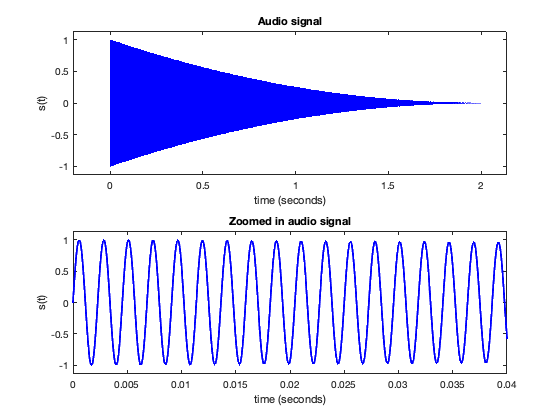

% Define note parameters
frequency =  440;
notelength = 2;
samplerate = 44100;
N = notelength * samplerate;

% Calculate the note signal
t = (0 : N) / samplerate;
note = sin(2 * pi * frequency * t);

% Reduce the amplitude over time
note = note .* ((notelength - t) / notelength) .^ 2;

% Plot the note signal
clf
subplot(2, 1, 1)
plot(t, note, 'b')
axis padded
title('Audio signal')
xlabel('time (seconds)')
ylabel('s(t)')

subplot(2, 1, 2)
plot(t, note, 'b', 'linewidth', 2)
axis padded
xlim([0, 0.04])
title('Zoomed in audio signal')
xlabel('time (seconds)')
ylabel('s(t)')

Click on the button below to play the note.

soundsc(note, samplerate)
 

The note with the frequency 440 Hz is known in music as the note **A4** or **A over middle C** (middle C is the note near the middle of the range of pitch of a piano). This note is used as the standard reference for tuning modern western instruments. Try experimenting with changing the frequency and length parameters to produce other notes (a list of the different frequencies for the notes on a piano can be found on [wikipedia](https://en.wikipedia.org/wiki/Piano_key_frequencies).

### Generating a musical chord

As well as individual notes, music is also played using **chords** which are a combination of three or more different notes played at the same time. For example, the A chord consists of the notes A, C# and E.

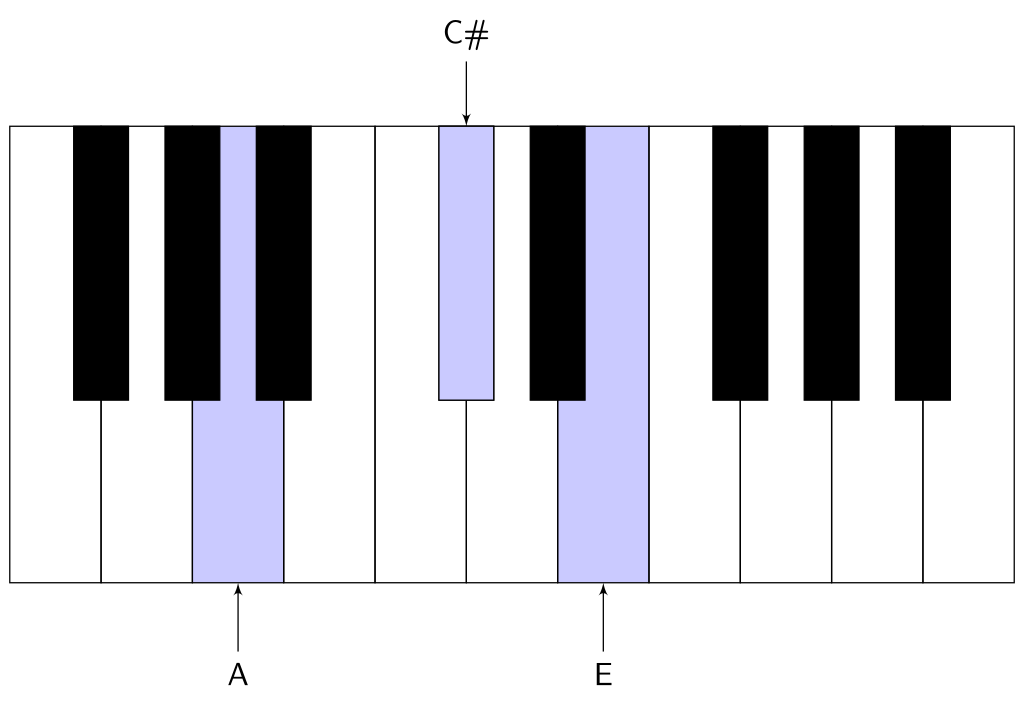

We can generate an audio signal of a chord by adding together the sine waves for each of the individual notes. The frequencies of the notes in a chord are related by a **frequency ratio** which are given in the table below for the most common type of chords. 


$$\begin{array}{lc}
\text{Chord} & \text{Frequency ratio} \\
\hline
\text{Major} & 4:5:6 \\
\text{Minor} & 10:12:15 \\
\text{Diminished} & 20:24:29 \\
\text{7th} & 20:25:30:36 \\
\hline 

\end{array}$$


Since the note A4 has a frequency of 440 Hz, and the major chord has the frequency ratio 4:5:6 so the two other notes in the A4 major chord (C#5 and E5) have frequencies $\frac{5}{4} \times 440 = 550$ Hz and $\frac{6}{4} \times 440 = 660$ Hz . The first note in the chord is known as the **root note**. Therefore the signal for the A4 chord is


$$s(t) = \sin(440\times 2 \pi t) + \sin(550\times 2 \pi t) + \sin(660 \times 2 \pi t).$$


The code below generates a signal of length 2 seconds of a musical chord defined by the frequency of the root note and the frequency ratio. 

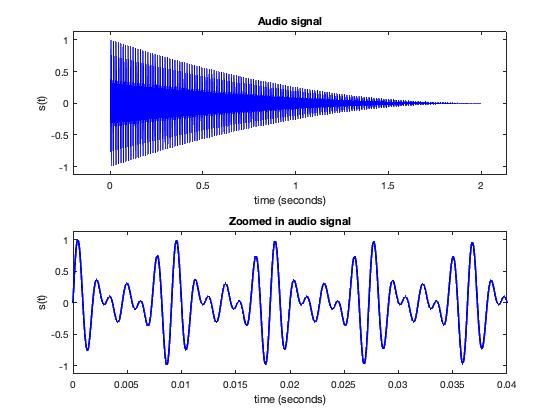

% Define note parameters
frequency =  440;
ratio = [4, 5, 6, 0];
chordlength = 2;
samplerate = 44100;
N = chordlength * samplerate;

% Calculate the note signal
t = (0 : N) / samplerate;
chord = zeros(size(t));
for i = 1 : length(ratio)
    chord = chord + sin(ratio(i) / ratio(1) * frequency * 2 * pi * t);
end
chord = chord / max(abs(chord));

% Reduce the amplitude over time
chord = chord .* ((chordlength - t) / chordlength) .^ 2;

% Plot the note signal
clf
subplot(2, 1, 1)
plot(t, chord, 'b')
axis padded
title('Audio signal')
xlabel('time (seconds)')
ylabel('s(t)')

subplot(2, 1, 2)
plot(t, chord, 'b', 'linewidth', 2)
axis padded
xlim([0, 0.04])
title('Zoomed in audio signal')
xlabel('time (seconds)')
ylabel('s(t)')

Click on the button below to play the chord.

soundsc(chord, samplerate);
 

## Compressing audio signals

We have seen that audio signals are a collection of sine waves that are added together. We can use an amazing mathematical tool called the **Fourier transform**, named after the French mathematician Joseph Fourier, which can calculate the amplitudes and frequencies of the sine waves that form an audio signal. By analysing the sine waves in an audio signal we can remove frequencies that are inaudible to a human. Fourier discovered the Fourier series in 1822 when he was attempting to solve an equation to model the transfer of heat. It would have never had occurred to him that the Fourier transform would be used for analysing signals since the technology for recording, transmitting and analysing signals didn't exist until over a hundred years later. There are many examples in mathematics where a discovery has applications in other areas other than that which was the original intention, this is one of the things that makes mathematics such a fascinating subject.

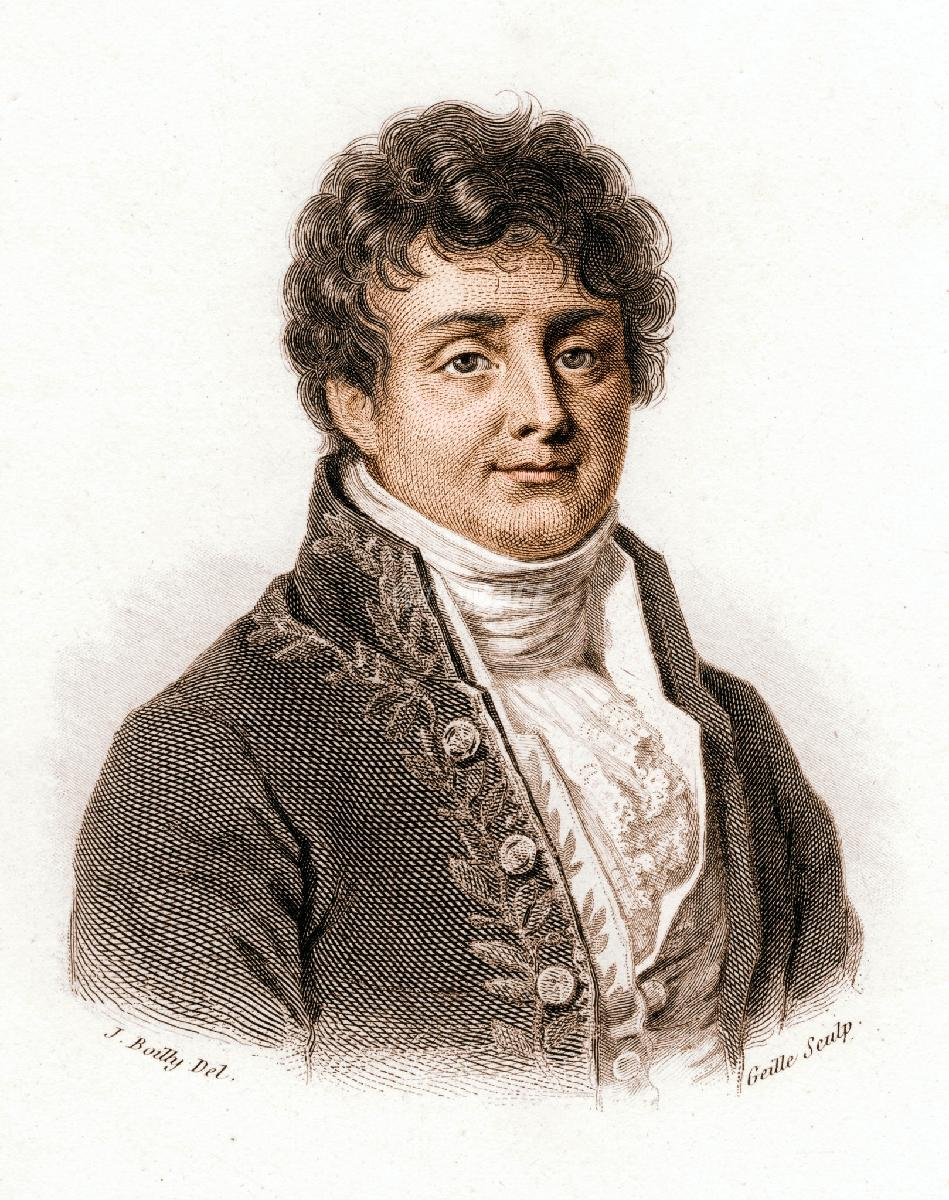

**Joseph Fourier (1778 - 1830)**

The following Python code reads the wave file `Fur_Elise.wav` which contains the first 12 seconds of a recording of a performance of Beethoven's *Fur Elise*. The code outputs the sample rate which the music was recorded, the number of sample points in the audio signal and the length of the signal in seconds.

% Read in the audio signal and output signal information
filename = "Fur_Elise.wav";
cd(fileparts(matlab.desktop.editor.getActiveFilename));
[signal, samplerate] = audioread(filename);
N = length(signal);
for i = 1 : 1
    fprintf('audio file        : %s', filename)
    fprintf('sample rate       : %1i Hz', samplerate)
    fprintf('no. sample points : %1i', N')
    fprintf('signal length     : %1.2f s', N / samplerate)
end

audio file        : Fur_Elise.wav

sample rate       : 44100 Hz

no. sample points : 529201

signal length     : 12.00 s

So the audio has been recorded using a sample rate of 44.1 kHz, the audio signal is made up of 529201 sample points so the length of the signal is $529201 \div 44100 = 12$ seconds. The code below plots the signal as well as a zoomed in portion of the signal allowing us to see the similarities between the audio signal and the sum of the sine waves from before. 

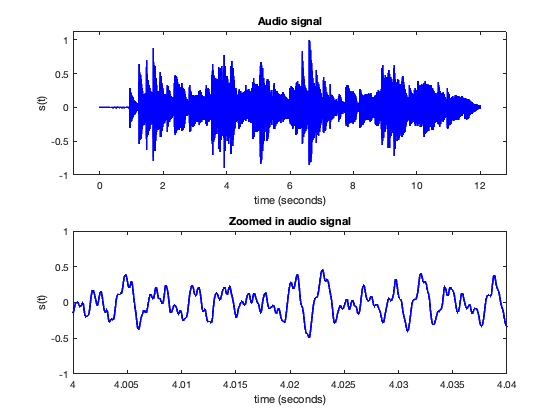

% Plot audio signal
t = (0 : N - 1) / samplerate;
for i = 1 : 2
    subplot(2, 1, i)
    plot(t, signal, 'b', 'linewidth', 2)
    xlabel('time (seconds)')
    ylabel('s(t)')
    ylim([-1, 1])
    axis padded
end

subplot(2, 1, 1);
title('Audio signal')
subplot(2, 1, 2)
title('Zoomed in audio signal')
axis([4, 4.04, -1, 1])

Click on the buttons below to play the signal.

audio = audioplayer(signal, samplerate);
play(audio)
 

stop(audio)
 

The Fourier transform converts a signal expressed over time (known as the **time domain**) to the amplitudes and frequencies of the sine waves that form the signal (known as the **frequency domain**). The following code calculates the Fourier transform for our audio signal and plots the amplitudes against the frequencies for each sine wave in the signal (this is known as the **frequency spectrum**). We can then see which sine waves dominate and which have much less of an effect on the sound we hear.

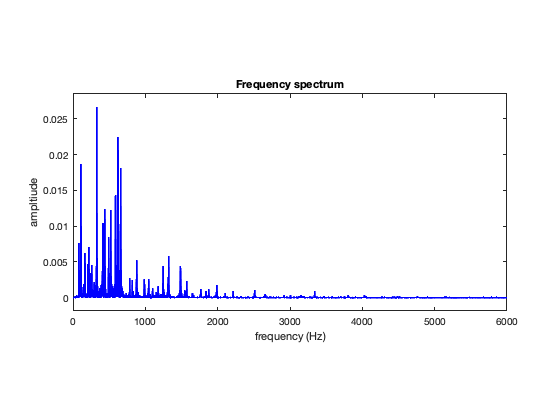

% Calculate the Fourier transform of the audio signal
fourier = fft(signal);

% Calculate the amplitude and frequencies using the Fourier transform
amplitude = 2 * abs(fourier / N);
frequency = (0 : N - 1) * samplerate / N;

% Plot amplitude against frequency
clf
plot(frequency, amplitude, 'b', 'linewidth', 2)
pbaspect([2, 1, 1])
axis padded
xlim([0, 6000])
title('Frequency spectrum')
xlabel('frequency (Hz)')
ylabel('ampltiude')

Here the sine waves with frequencies less than 4 kHz have the larger amplitudes and the higher frequencies have almost zero amplitude so we should be able to remove the sine waves with frequencies greater than 4 kHz and not notice a difference in the audio signal. This means we would can **compress** the audio signal so that it will require less memory and therefore easier to stream over the internet.

The code below removes all of the sine waves with frequencies higher than 4 kHz and reconstructs the compressed audio signal using the remaining sine waves.

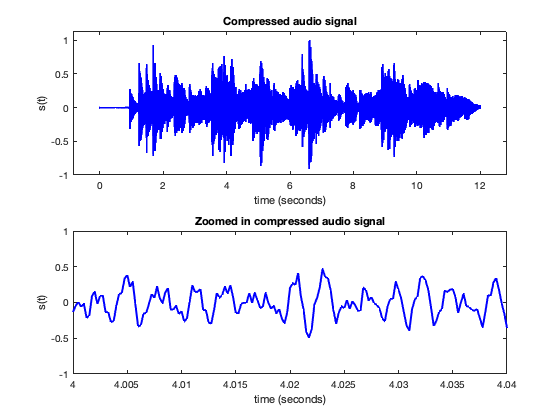

% Remove higher frequencies
threshold = 4000;
compressed_fourier = fourier(frequency < threshold);

% Reconstruct compressed signal
compressed_signal = real(ifft(compressed_fourier));
compressed_signal = compressed_signal / max(compressed_signal);
compressed_samplerate = threshold;
t = (0 : length(compressed_signal) - 1) / compressed_samplerate;

% Plot compressed signal
for i = 1 : 2
    subplot(2, 1, i)
    plot(t, compressed_signal, 'b', 'linewidth', 2)
    xlabel('time (seconds)')
    ylabel('s(t)')
    ylim([-1, 1])
    axis padded
end

subplot(2, 1, 1);
title('Compressed audio signal')
subplot(2, 1, 2)
title('Zoomed in compressed audio signal')
axis([4, 4.04, -1, 1])

Looking at the plots of the compressed signal they look very similar to the original signal above. Of course we have changed the original signal so we should play it to see (or more accurately hear) whether the compressed signal sounds the same.

audio = audioplayer(compressed_signal, threshold);
play(audio)
 

stop(audio)
 

You may hear some differences between the original signal and the reconstructed signal. The sizes of the original and compressed audio signals are outputted using the following code.

for i = 1 : 1
    fprintf('Size of the original signal   : %8i', N)
    fprintf('Size of the compressed signal : %8i', length(compressed_signal))
    fprintf('Compression rate (percentage) : %8.2f%%', (N - length(compressed_signal)) / N * 100)
end

Size of the original signal   :   529201

Size of the compressed signal :    48001

Compression rate (percentage) :    90.93%

So the compressed audio signal uses much less memory than the original signal so is easier to stream over the internet. The fewer sine waves that are removed the closer the reconstructed signal will be to the original, but of course this would require more memory.

### Streaming music to your device

The steps involved for going from the recording of a piece of music to you listening to it on your device are summarised in the flow chart below.

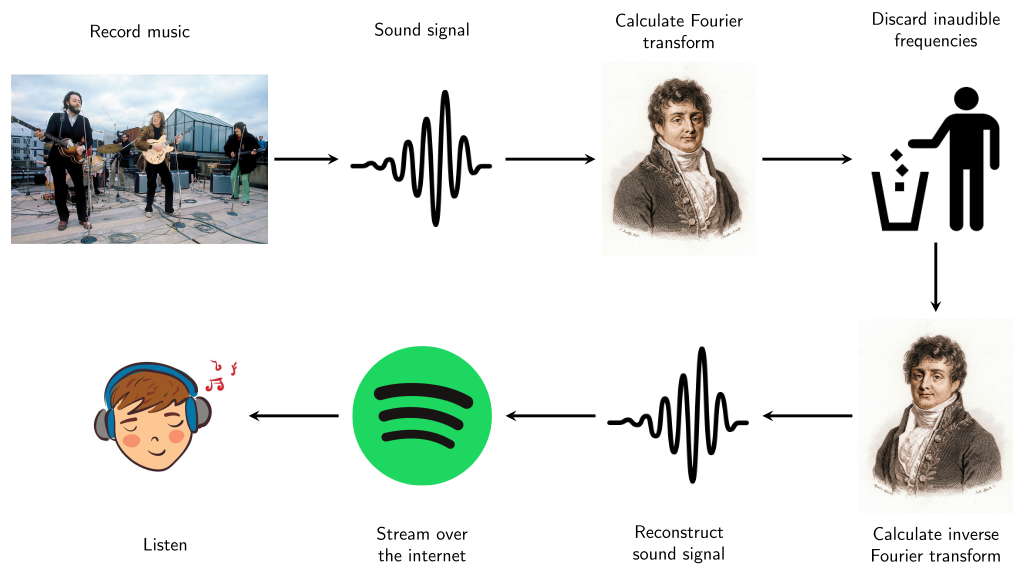

- The music is recorded, digitised and stored as on a computer.

- The Fourier transform is calculated so that we can analyse the amplitudes and frequencies of the sine waves in the signal.

- The frequencies that are inaudible to us are discarded (and some other techniques to reduce the memory needed to store the signal are also applied)

- The inverse Fourier transform is calculated and the compressed sound signal is reconstructed. 

- The compressed sound signal is streamed over the internet to your device allowing you to enjoy the music.

A similar method can be used to help reduce the memory required to store and transmit video signals and are used by applications such as YouTube, TikTok, Netflix etc. to make video streaming possible. Just think, without mathematics and the work of Joseph Fourier 200 years ago, this would not be possible!